data_basefolder = "H:\Data_connectome\trace_pipe_DJ";

%fill this section for input
animal = 4086;
filter_timesbg = 3; %3 is standard Guassian asssumption

%export the color-- raw pixel value
braincolor = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'pixel_raw');
if (~isfolder(braincolor))
    mkdir(braincolor);
    fprintf('making folder %s\n', braincolor);
else
    fprintf('Folder exist: %s\n', braincolor);
end

making folder H:\Data_connectome\trace_pipe_DJ\4086\exported_color\brain\pixel_raw



retinacolor = fullfile(data_basefolder, string(animal), ...
    'exported_color', 'retina', 'pixel_raw');
if (~isfolder(retinacolor))
    mkdir(retinacolor);
    fprintf('making folder %s\n', retinacolor);
else
    fprintf('folder exsits %s\n', retinacolor);
end

making folder H:\Data_connectome\trace_pipe_DJ\4086\exported_color\retina\pixel_raw


export_spd_color(animal, true, true, braincolor);

load data... it may takes a while....
exporting color data of image 1092
exporting color data of image 1093
exporting color data of image 1094
exporting color data of image 1095
exporting color data of image 1096
exporting color data of image 1097
exporting color data of image 1098
exporting color data of image 1099


export_spd_color(animal, false, true, retinacolor);

exporting color data of image 1100
exporting color data of image 1091
exporting color data of image 1089
exporting color data of image 1088


%filter through Guassian background -- brain
filtered_path = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'bg_std_filt');
if (~isfolder(filtered_path))
    mkdir(filtered_path);
end
csv_files = dir(fullfile(braincolor, '*.csv'));
num_files = length(csv_files);
br_imids = zeros([num_files, 1]);
for i = 1:num_files
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    br_imids(i) = image_id;
    t = readtable(fullfile(braincolor, csv_files(i).name));

    bg = get_background(image_id, true);

    %filter by 3times background frame mean
    bgstd = std(bg, 0, [1 2]);
    [~, ~, row, col] = size(bgstd);
    bgstd = reshape(bgstd, [row col]);

    bgfilename = sprintf('background_im%d.csv', image_id);
    %save a copy of the background as well
    T = array2table(bgstd, 'VariableNames',{'c1', 'c2', 'c3'});
    writetable(T, fullfile(braincolor, bgfilename));

    filtered = GuassianBgFlit_withT(t, bgstd,3, filter_timesbg);

    %save filtered
    wrT = array2table(filtered, 'VariableNames',{'c1', 'c2', 'c3', 'fr'});
    filtName = sprintf('%d_axon_pixel_filtered.csv', image_id);
    writetable(wrT, fullfile(filtered_path, filtName));
end

Getting the background of image 1092...
Getting the background of image 1093...
Getting the background of image 1094...
Getting the background of image 1095...
Getting the background of image 1096...
Getting the background of image 1097...
Getting the background of image 1098...
Getting the background of image 1099...


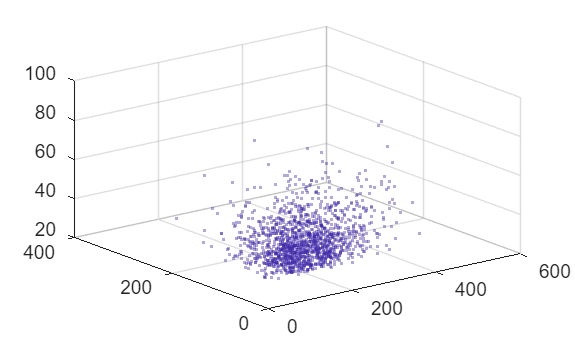

image index: 1
Press any key to continue....
image index: 2
Press any key to continue....
image index: 3
Press any key to continue....
image index: 4
Press any key to continue....
image index: 5
Press any key to continue....
image index: 6
Press any key to continue....
image index: 7
Press any key to continue....


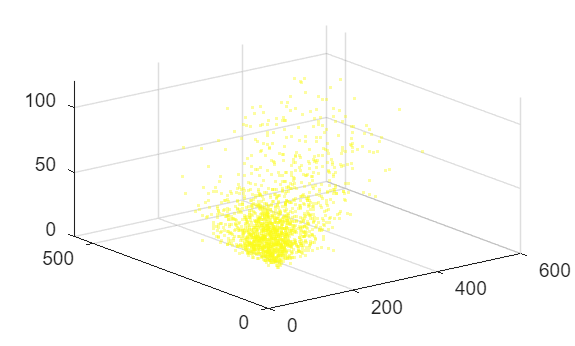

image index: 8
Press any key to continue....


%plot to see if there is splitting
%TAKE A NOTE OF THE INDEXES OF THE SPLITING PIXEL IMAGE
fig = figure;
clf(fig);
xlabel('c1');
ylabel('c2');
zlabel('c3');
colors = parula(num_files);
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:num_files
    t = readtable(fullfile(filtered_path, csv_files(i).name));
    scatter3(t.c1, t.c2, t.c3, 20, colors(i, :), '.', 'MarkerEdgeAlpha', 0.4);
    fprintf('image index: %d\nPress any key to continue....\n', i);
    % w = waitforbuttonpress;    
end

%FILL OUT THIS LIST
spliting_list = [];
%------------------------------------------------------------------------

%spliting the pixels into 2 clusters
split_folder = fullfile(data_basefolder, string(animal), ...
    'exported_color','brain', 'brain_codeprep');
if (~isfolder(split_folder))
    mkdir(split_folder);
    fprintf('Making folder %s\n', split_folder);
end

Making folder H:\Data_connectome\trace_pipe_DJ\4086\exported_color\brain\brain_codeprep


csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:numel(spliting_list)
    
    imidx = br_imids(spliting_list(i));
    fprintf('%d. dealing image %d...\n',i, imidx);
    t = readtable(fullfile(filtered_path, csv_files(spliting_list(i)).name));
    [cluster1, cluster2] = separate_2PxCluster(t);
    fig = figure;
    clf(fig);
    hold on;
    scatter(cluster1.c1, cluster1.c2);
    scatter(cluster2.c1,  cluster2.c2);
    hold off;
    fprintf('Press any key to continue...\n');

    spn1 = sprintf('%d_major_filtered.csv', imidx);
    %spn2 = sprintf('%d_minor_filtered.csv', br_imids(imidx));
    writetable(cluster1, fullfile(split_folder, spn1));
    %writetable(cluster2, fullfile(split_folder, spn2));
end

total_list = linspace(1, num_files, num_files);
non_spliting = setdiff(total_list, spliting_list);
for j = 1:numel(non_spliting)
    index = non_spliting(j);
    oldpath = fullfile(filtered_path, csv_files(index).name);
    newpath = fullfile(split_folder, csv_files(index).name);
    movefile(oldpath, newpath);
end
fprintf('All filtered color coding files are in this folder:\n');

All filtered color coding files are in this folder:


fprintf('%s\n', split_folder);

H:\Data_connectome\trace_pipe_DJ\4086\exported_color\brain\brain_codeprep


%filter the background retina
filtered_path = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'retina', 'bg_std_filt');
if (~isfolder(filtered_path))
    mkdir(filtered_path);
    fprintf('Made folder for retina filter\n%s\n', filtered_path);
end
csv_files = dir(fullfile(retinacolor, '[0-9]*.csv'));
num_files = length(csv_files);
br_imids = zeros([num_files, 1]);
for i = 1:num_files
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    br_imids(i) = image_id;
    t = readtable(fullfile(retinacolor, csv_files(i).name));

    bg = get_background(image_id, false);

    %filter by 3times background frame mean
    bgstd = std(bg, 0, [1 2]);
    [~, ~, row, col] = size(bgstd);
    bgstd = reshape(bgstd, [row col]);

    bgfilename = sprintf('background_im%d.csv', image_id);
    %save a copy of the background as well
    T = array2table(bgstd, 'VariableNames',{'c1', 'c2', 'c3'});
    writetable(T, fullfile(retinacolor, bgfilename));

    filtered = GuassianBgFlit_withT(t, bgstd,3, filter_timesbg);

    %save filtered
    wrT = array2table(filtered, 'VariableNames',{'c1', 'c2', 'c3', 'fr'});
    filtName = sprintf('%d_rgc_pixel_filtered.csv', image_id);
    writetable(wrT, fullfile(filtered_path, filtName));
end

Getting the background of image 1088...
Getting the background of image 1089...
Getting the background of image 1091...
Getting the background of image 1100...
Getting the background of image NaN...


Error using mym
Unknown column 'NaN' in 'where clause'

Error in dj.Connection/query (line 183)
                ret=mym(self.connId, queryStr, v{:});
                ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in dj.internal.GeneralRelvar/fetch (

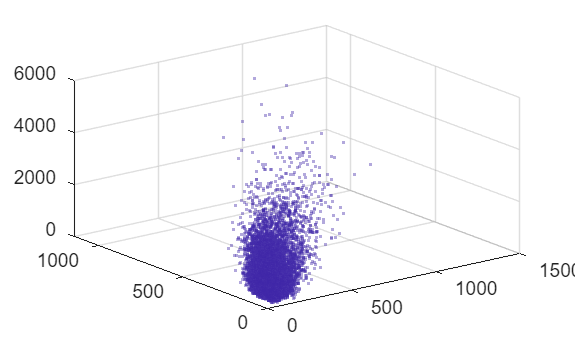

image index: 1
Press any key to continue....
image index: 2
Press any key to continue....
image index: 3
Press any key to continue....


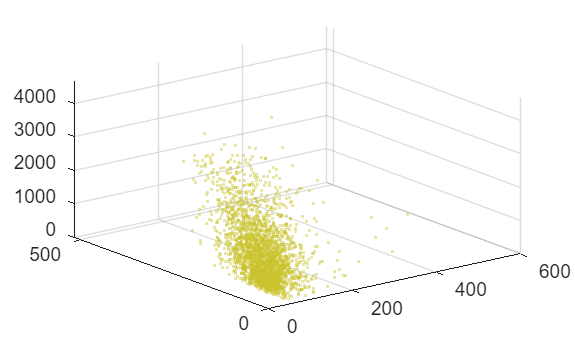

image index: 4
Press any key to continue....


Index exceeds the number of array elements. Index must not exceed 4.

%plot to see if there is splitting -- RETINA
%TAKE A NOTE OF THE INDEXES OF THE SPLITING PIXEL IMAGE
fig = figure;
clf(fig);
xlabel('c1');
ylabel('c2');
zlabel('c3');
colors = parula(num_files);
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:num_files
    t = readtable(fullfile(filtered_path, csv_files(i).name));
    scatter3(t.c1, t.c2, t.c3, 20, colors(i, :), '.', 'MarkerEdgeAlpha', 0.4);
    fprintf('image index: %d\nPress any key to continue....\n', i);
end

%Retina images should not have any splitting... skipping this

% %FILL OUT THIS LIST
% spliting_list = [5, 6, 8, 10];
% %------------------------------------------------------------------------
% total_list = linspace(1, num_files, num_files);
% non_spliting = setdiff(total_list, spliting_list);
% %spliting the pixels into 2 clusters
% split_folder = fullfile(data_basefolder, string(animal), ...
%     'exported_color','retina', 'retina_codeprep');
% csv_files = dir(fullfile(filtered_path, '*.csv'));
% for i = 1:numel(spliting_list)
% 
%     imidx = spliting_list(i);
%     fprintf('%d, dealing image %d...\n',i, imidx);
%     t = readtable(fullfile(filtered_path, csv_files(imidx).name));
%     [cluster1, cluster2] = separate_2PxCluster(t);
%     fig = figure;
%     clf(fig);
%     hold on;
%     scatter(cluster1.c1, cluster1.c2);
%     scatter(cluster2.c1,  cluster2.c2);
%     hold off;
%     fprintf('Press any key to continue...\n');
% 
%     spn1 = sprintf('%d_major_filtered.csv', br_imids(imidx));
%     %spn2 = sprintf('%d_minor_filtered.csv', br_imids(imidx));
%     writetable(cluster1, fullfile(split_folder, spn1));
%     %writetable(cluster2, fullfile(split_folder, spn2));
% end
% 
% %move the rest of the tables to the same folder
% for j = 1:numel(non_spliting)
%     index = non_spliting(j);
%     oldpath = fullfile(filtered_path, csv_files(index).name);
%     newpath = fullfile(split_folder, csv_files(index).name);
%     movefile(oldpath, newpath);
% end
% fprintf('All filtered color coding files are in this folder:\n');
% fprintf('%s\n', split_folder);

%---------------Filtering completed now color coding-----------------

%color coding by the most prominent features
%MOVE THE USEABLE CSV PIXEL TO THE FOLDER FIRST
codingfolder = fullfile(data_basefolder, string(animal), ...
    'exported_color', 'brain', 'brain_codeprep');
csv_files = dir(fullfile(codingfolder, '*.csv'));
num_files = numel(csv_files);
slopes = zeros(num_files, 3);
intercepts = zeros(num_files, 3);
median_br = zeros([num_files, 3]);
for i = 1:num_files
    t = readtable(fullfile(codingfolder, csv_files(i).name));
    model1 = fitlm(t.c1, t.c2);
    slopes(i, 1) = model1.Coefficients.Estimate(2);
    intercepts(i, 1) = model1.Coefficients.Estimate(1);
    median_br(i,1) = median(t.c1);
    
    model2 = fitlm(t.c2, t.c3);
    slopes(i, 2) = model2.Coefficients.Estimate(2);
    intercepts(i, 2) = model2.Coefficients.Estimate(1);
     median_br(i,2) = median(t.c2);

    model3 = fitlm(t.c1, t.c3);
    slopes(i, 3) = model3.Coefficients.Estimate(2);
    intercepts(i, 3) = model3.Coefficients.Estimate(1);
     median_br(i,3) = median(t.c3);

end
repre2 = [slopes(:, 2:3) intercepts(:, 1)];


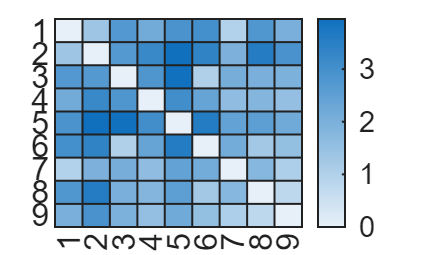

%visualize the brain axon image clusters
w = std(repre2, 0, 1);
weighted_repre2 = repre2./w;
dist = zeros([height(repre2) height(repre2)]);
for i = 1:height(repre2)
    for j = 1:height(repre2)
        dist(i,j) = norm(weighted_repre2(i, :) - weighted_repre2(j, :));
    end
end
heatmap(dist);

%load rgc axons and color linear regression
folder_path_b = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\retina_codeprep";
csv_files_b = dir(fullfile(folder_path_b, '*.csv'));

num_files_b = length(csv_files_b);
ret_imids = zeros([num_files_b, 1]);
slopes_b = zeros([num_files_b, 3]);
intercepts_b = zeros([num_files_b, 3]);

for i = 1:num_files_b
    file_path = fullfile(folder_path_b, csv_files_b(i).name);
    image_id = regexp(csv_files_b(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    ret_imids(i) = image_id;
    
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes_b(i, 1) =table2array(model1.Coefficients(2,1));
    intercepts_b(i, 1) = model1.Coefficients.Estimate(1);
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes_b(i, 2) = table2array(model2.Coefficients(2,1));
    intercepts_b(i, 2) = model2.Coefficients.Estimate(1);

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes_b(i, 3) = table2array(model3.Coefficients(2,1));
    intercepts_b(i, 3) = model3.Coefficients.Estimate(1);
end
repre3 = [slopes_b(:, 2:3) intercepts_b(:, 2)];

%plot both types of image color coding together
fig = figure;
clf(fig);
hold on;
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3), 'magenta', 'filled');
for i = 1:num_files
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre2(i, 1), repre2(i, 2), repre2(i, 3), string(i));
end
scatter3(repre3(:, 1), repre3(:, 2),  repre3(:, 3), 'cyan', 'filled');
for i = 1:height(repre3)
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre3(i, 1), repre3(i, 2), repre3(i, 3), string(i));
end
grid on;
hold off;

%save the codings to csv just in case
codingFolder = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'coding');
filepath = fullfile(codingFolder, 'Axon_coding.csv');
t = array2table(repre2, 'VariableNames', {'f1', 'f2', 'f3'});
writeable(t, filepath);

filepath = fullfile(codingFolder, 'RGC_coding.csv');
t = array2table(repre3, 'VariableNames', {'f1', 'f2', 'f3'});
writetable(t, filepath);

%real match process starts
% 1. features already prepared (your step 1, raw)
%    X_rgc  : n x F  RGC features
X_rgc = repre3;
%    Y_axon : n x F  axon features      (F = 3: [s23, s13, b23])
%Y_axon = repre2;
% 2. per-feature brain-space balancing scale — COMPUTE ONCE, HERE.
w = std(Y_axon, 0, 1);          % 1 x F, spread of each feature across axons
%   alternatives, pick one and keep it fixed:
%   w = median(abs(Y_axon - median(Y_axon,1)), 1) * 1.4826;   % MAD
%   w = median(Y_axon, 1);                                     % median-divide
%   (NOT ones — that's the bug you just found)

% 3. score all permutations (w threaded in, same for every permutation)
results = match_permute(X_rgc, Y_axon, w);

% 4. pick the match under sign + topographic constraints
slope_idx = [1 2];              % s23, s13 must have >=0 diagonal; b23 exempt
[best, rank_found, diag_info] = pick_match(results, constr, slope_idx);